timemax=20;
t=0;
samplingRate=1500;
inicio=1;
while t<timemax
    load('EMG 2 channel Wrist Flex_Ext_Raw.mat');
    paquete=Data{2}(inicio:inicio+samplingRate);
    
    
    tiempo=tiempo+1;
    inicio=samplingRate+inicio;
    
end

%Definiendo el tiempo durante el cual se desea capturar la señal (segundos)
tmax=30;%Tiempo de captura en segundos

%Procedimiento para preparar la figura donde se mostraran las graficas
%Creando la figura con el titulo___
f=figure("Name","Aplicaciones de ingenieria con matlab");
%Establecimiento de limites de la grafica
a=axes("XLim",[0 tmax],"YLim",[0 5]);
l1=line(nan,nan,"Color","r","LineWidth",2);
%Cambio de las etiquetas en los ejes
%Activando cuadricula
grid on
%Manteniendo graficas
hold on
%Contador de lecturas realizadas
i=1;
%Tiempo inicial
%Comenzando a cronometrar
tic

%Repetimos mi
while (t<tmax)
    %tiempo en que llega la siguiente lectura
    t=toc;
    %Leyendo el dato del puerto serial en formato decimal
    a=fscanf(s,'%d');
    %Conviertiendo el valor obtenido por el AD a voltaje
    v1(i)=a(1)*3.28/1023;
    %Mostramos el tiempo en el titulo de la grafica
    title(['t=' num2str(round(t*10)/10)]);
    %Linealizamos los valores en x
    x=linspace(0,t,i);
    %Asignamos los valores de voltaje y la linealizacion del tiempo a la
    %linea
    set(l1,'YData',v1(1:(i)),'XData',x);%Graficando para cada valor de V Mantenemos la grafica anterior
    %Mantenemos la grafica anterior
    hold on;
    %Comando drawnow para dibujar inmediatamente
    drawnow;
    %Aumentamos el indice de las tablas de valores
    i=i+1;
end


%Eliminando conexiones existentes
delete(instrfind({'Port'},{'COM4'}));
%Creando objeto serial definiendo como terminador un retorno de carrro
s=serial('COM4','BaudRate',9600,'Terminator','CR/LF');
%Abriendo el puerto serie
fopen(s);


p=0;
mensaje='Estabilizando comunicacion';
tic
while p<20
    a=fscanf(s,'%d');
    p=p+1;
end
tiempoprueba=toc
mensaje='Comunicacion estable'

%Definiendo el tiempo durante el cual se desea capturar la señal (segundos)
tmax=30;%Tiempo de captura en segundos

%Procedimiento para preparar la figura donde se mostraran las graficas
%Creando la figura con el titulo___
f=figure("Name","Aplicaciones de ingenieria con matlab");
%Establecimiento de limites de la grafica
a=axes("XLim",[0 tmax],"YLim",[0 3.28]);
l1=line(nan,nan,"Color","r","LineWidth",2);
%Cambio de las etiquetas en los ejes
%Activando cuadricula
grid on
%Manteniendo graficas
hold on
%Contador de lecturas realizadas
i=1;
%Tiempo inicial
%Comenzando a cronometrar
tic

%Repetimos mi
while (t<tmax)
    %tiempo en que llega la siguiente lectura
    t=toc;
    %Leyendo el dato del puerto serial en formato decimal
    a=fscanf(s,'%d');
    %Conviertiendo el valor obtenido por el AD a voltaje
    v1(i)=a(1)*3.28/1023;
    %Mostramos el tiempo en el titulo de la grafica
    title(['t=' num2str(round(t*10)/10)]);
    %Linealizamos los valores en x
    x=linspace(0,t,i);
    %Asignamos los valores de voltaje y la linealizacion del tiempo a la
    %linea
    set(l1,'YData',v1(1:(i)),'XData',x);%Graficando para cada valor de V Mantenemos la grafica anterior
    %Mantenemos la grafica anterior
    hold on;
    %Comando drawnow para dibujar inmediatamente
    drawnow;
    %Aumentamos el indice de las tablas de valores
    i=i+1;
end

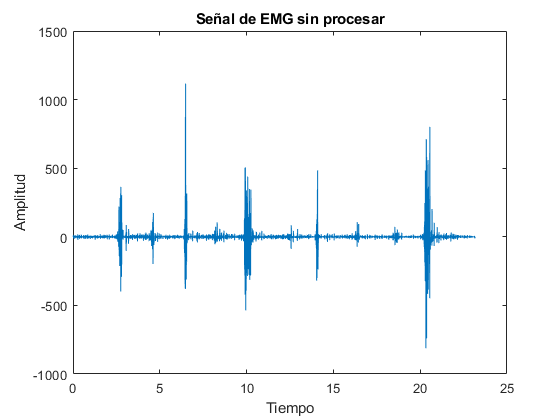


load('EMG 2 channel Wrist Flex_Ext_Raw.mat')

Fs = 1500;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 34740;             % Length of signal
t = (0:L-1)*T;        % Time vector
X=Data{2};

plot(t,X)
title('Señal de EMG sin procesar')
xlabel('Tiempo')
ylabel('Amplitud')

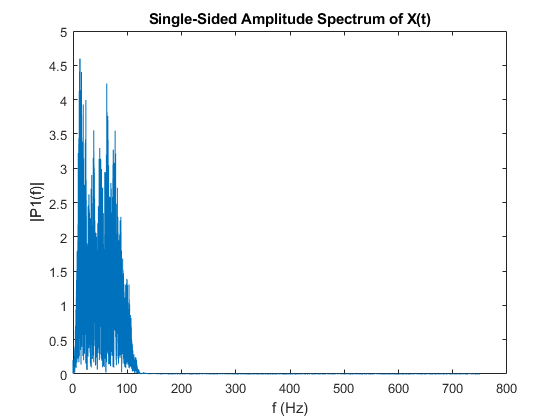



Y = fft(X);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')